## **Digital Communication Systems Laboratory**

## **Laboratory 07**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

clc; clear;
%TU ID: 915614617
A = 1;              % Signal amplitude
rb = 2;          % Fundamental frequency of signal
Tb = 1 / rb;        % Period of signal
fc = (6+20) * rb;
Tc = 1 / fc;
fs = 100 * fc;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

#### **Modulation**

In the baseband:

    
$$s_{\textrm{base}} \left(t\right)=A\;\sin \left(\;2\pi \;f\;t+\theta \;\right)$$


    If the message is embedded in the amplitude A, the encoding is called Amplitude Shift Keying (ASK).

    If the message is embedded in the frequency *f*, the encoding is called Frequency Shift Keying (FSK).

    If the message is embedded in the phase $\theta$, the encoding is called Phase Shift Keying (PSK).

    If the message is mebedded in the amplitude A and phase $\theta$, the encoding is called Quadrature Amplitude Modulation (QAM).

In the passband, the wave spectrum is transfered from the origin to a higher frequency, called as frequency of carrier or fc.

    
$$s_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\theta \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$


### Section 03

#### Quadrature Amplitude Modulation (QAM)

Suppose there are 16 symbols in the symbol set. Therefore, at least 4 bits are needed to encode the symbols in binary format.

M = 16;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol

In QAM encoding, the amplitude and phase will carry the information. So, the amplitude and phase of the sinosoid will be changed by the symbols.

For example:

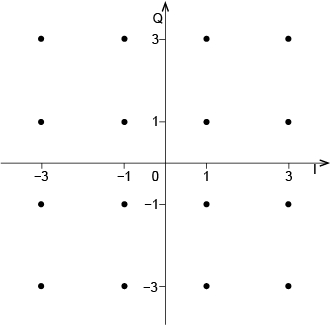

Symbols                In-Phase              Quadrature            Phase (rad) = $\tan^{-1} \left(\frac{Q}{I}\right)$

    1                            A                             A                            $\frac{\pi }{4}$

    2                            -A                            A                            $\frac{3\pi }{4}$

    3                            -A                            -A                           $\frac{5\pi }{4}$

    4                            A                             -A                            $\frac{7\pi }{4}$

    ...                           ...                            ...                            ...

    16                         3A                            -A                            6.6049

This symbol sets can be shown in the original indices and the PSK encoded format:

symbol_set = 1:M;                           % symbols' indices
%symbol_coords = A * [1+1j, -1+1j, -1-1j, 1-1j, 3+1j, 3+3j, 1+3j, -1+3j, -3+3j, -3+1j, -3-1j, -3-3j, -1-3j, 1-3j, 3-3j, 3-1j];  % symbols' phase
%figure(); 

%symbol_coords = A * [1+1j, -1+1j, -1-1j, 1-1j, 3+1j, 3+3j, 1+3j, -1+3j, -3+3j, -3+1j, -3-1j, -3-3j, -1-3j, 1-3j, 3-3j, 3-1j];  % symbols' phase
TU5=1/10;   %TUID (5)/10
TU6=4/10;   %TUID (6)/10
symbol_coords=A*[((1+TU5)+(1+TU6)*1j),((-1-TU5)+(-1+TU6)*1j),((-1-TU5)+(-1-TU6)*1j),((1+TU5)+(-1-TU6)*1j),((3+TU5)+(1+TU6)*1j),((3+TU5)+(3+TU6)*1j),((1+TU5)+(3+TU6)*1j),((-1-TU5)+(3+TU6)*1j),((-3-TU5)+(3+TU6)*1j),((-3-TU5)+(1+TU6)*1j),(-3-TU5)+(-1-TU6*1j),((-3-TU5)+(-3-TU6)*1j),((-1-TU5)+(-3-TU6)*1j),((1+TU5)+(-3-TU6)*1j),((3+TU5)+(-3-TU6)*1j),((3+TU5)+(-1-TU6)*1j)]

symbol_coords =    1.1000 + 1.4000i  -1.1000 - 0.6000i  -1.1000 - 1.4000i   1.1000 - 1.4000i   3.1000 + 1.4000i   3.1000 + 3.4000i   1.1000 + 3.4000i  -1.1000 + 3.4000i  -3.1000 + 3.4000i  -3.1000 + 1.4000i  -4.1000 - 0.4000i  -3.1000 - 3.4000i  -1.1000 - 3.4000i   1.1000 - 3.4000i   3.1000 - 3.4000i   3.1000 - 1.4000i


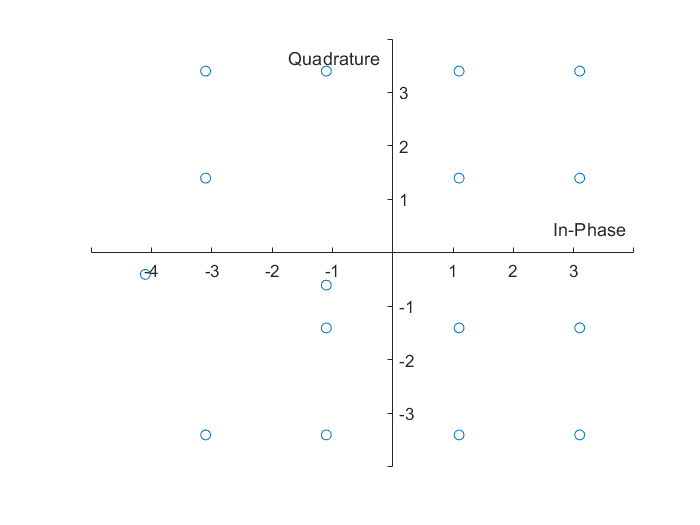

figure(); 


scatter(real(symbol_coords), imag(symbol_coords))
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
xlabel('In-Phase'); ylabel('Quadrature');

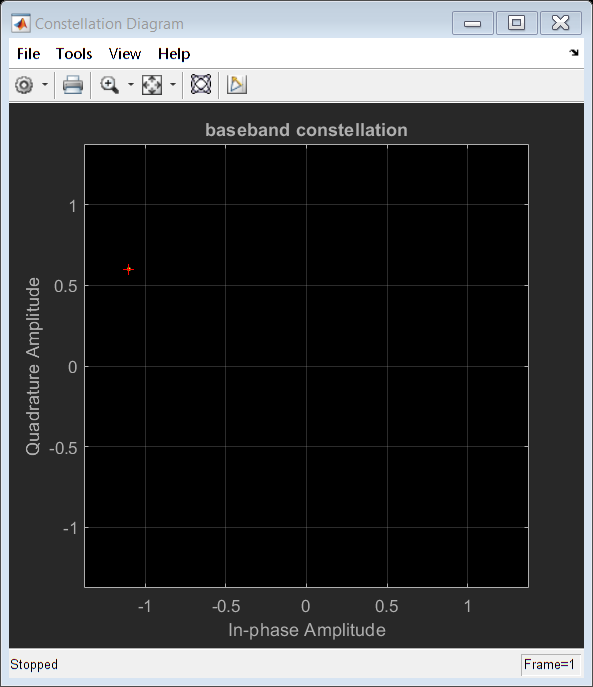

constdiag = comm.ConstellationDiagram;
constdiag.Title = "baseband constellation";
% constdiag.SymbolsToDisplay = 10000;
constdiag.ShowLegend = false;
constdiag.ReferenceConstellation = symbol_coords';
constdiag(symbol_coords');
constdiag.release();

%msg = 1:M;                                  % message: a set of symbols
msg=[9 1 5 6 1 4 6 1 7]

msg =      9     1     5     6     1     4     6     1     7


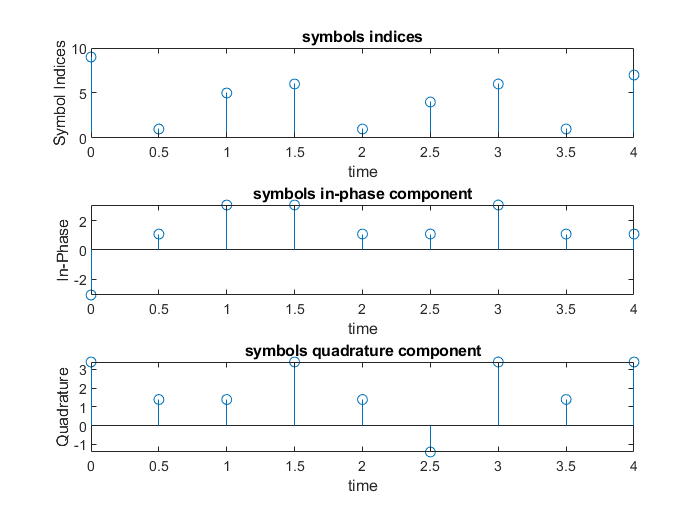

msg_coords = symbol_coords(symbol_set(msg));  % mepping the symbol to the phase
t = (0:length(msg)-1)*Tb;
figure()
subplot(3, 1, 1); stem(t, msg); xlabel('time'); ylabel('Symbol Indices'); title('symbols indices');
subplot(3, 1, 2); stem(t, real(msg_coords)); xlabel('time'); ylabel('In-Phase'); title('symbols in-phase component');
subplot(3, 1, 3); stem(t, imag(msg_coords)); xlabel('time'); ylabel('Quadrature'); title('symbols quadrature component');

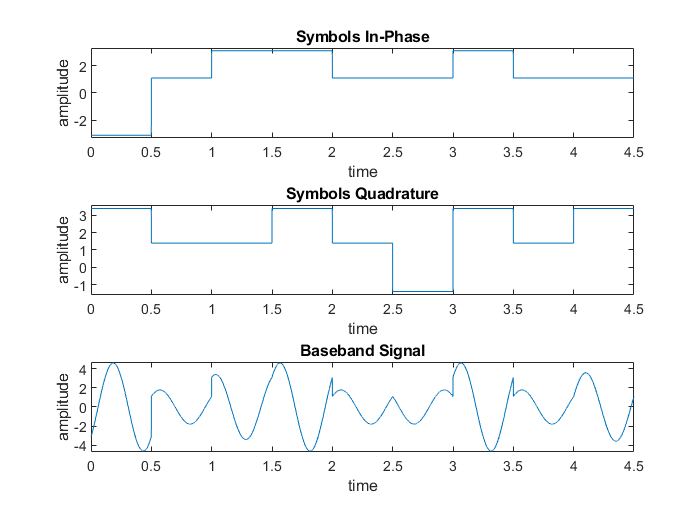

msg_coords_fs = rate_transition(msg_coords, rb, fs);
t = (0:length(msg_coords_fs)-1)*Ts;
signal = A * real(msg_coords_fs) .* cos(2 * pi * rb * t) + A * imag(msg_coords_fs) .* sin(2 * pi * rb * t);
figure()
subplot(3, 1, 1); plot(t, real(msg_coords_fs)); xlabel('time'); ylabel('amplitude'); ylim([min(real(msg_coords_fs))-0.2, max(real(msg_coords_fs))+0.2]); title('Symbols In-Phase')
subplot(3, 1, 2); plot(t, imag(msg_coords_fs)); xlabel('time'); ylabel('amplitude'); ylim([min(imag(msg_coords_fs))-0.2, max(imag(msg_coords_fs))+0.2]); title('Symbols Quadrature')
subplot(3, 1, 3); plot(t, signal); xlabel('time'); ylabel('amplitude'); ylim([min(signal)-0.1, max(signal)+0.1]); title('Baseband Signal');

The baseband signal is modulated with carrier signal and the spectrum will shift in frequency domain from around the origin to the $f_c$ Hertz.

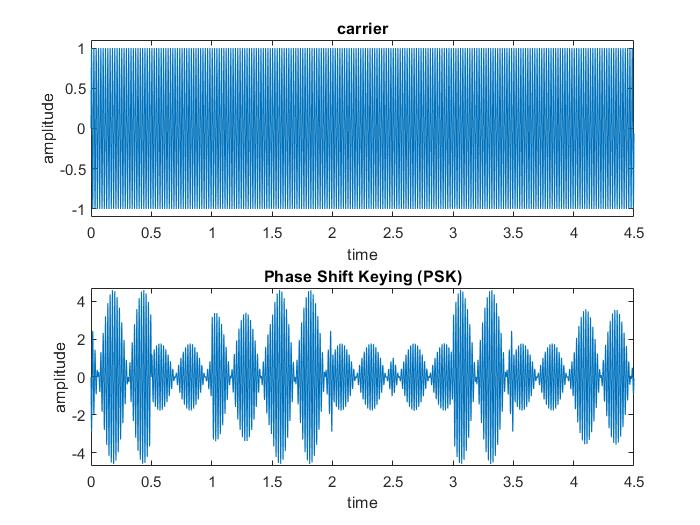

carrier = 1 * sin(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t, carrier); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t, modulated); xlabel('time'); ylabel('amplitude'); ylim([min(signal)-0.1, max(signal)+0.1]); title('Phase Shift Keying (PSK)');

### Section 04

#### Demodulation, Decoding, and Detection

Demodulation is the inverse of modulation, but the operation is the same.


$$r_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$



$$r_{\textrm{base}} \left(t\right)=\int_0^{T_c } r_{\textrm{pass}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}=\int_0^{T_c } s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}$$


Since it is assumed that $r_b \ll f_c$, it can be found that the variation of $s_{\textrm{base}} \left(t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)$ is much less than $\cos \left(2\pi \;f_c \;t\right)$ in one period of carrier frequency ($T_c$). Therefore, it can be assumed that $s_{\textrm{base}} \left(t\right)$is almost constant in one cycle of carrier and the integral can be rewriten as:


$$r_{\textrm{base}} \left(t\right)\approx s_{\textrm{base}} \left(t\right)\int_0^{T_c } \cos^2 \left(2\pi \;f_c \;t\right)\textrm{dt}=\frac{s_{\textrm{base}} \left(t\right)}{2}\int_0^{T_c } 1+\cos \left(4\pi \;f_c \;t\right)\;\textrm{dt}=\frac{T_c }{2}s_{\textrm{base}} \left(t\right)$$


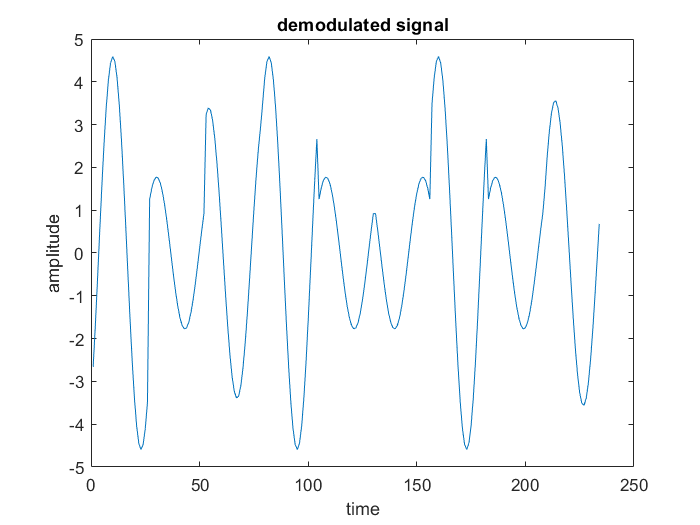

% demodulation
rt = modulated;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
figure()
plot(demodulated); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

Decoding tries to find the indices of transmitted symbols.

Detection means finding the message that has been transmitted.

There are several methods to decode the received signal, but the correlation decoder is the most common. The matched filter is an LTI implementation of correlator, so both are the same with different formulation.

If the received signal is $r\left(t\right)$ and the base encoding signal is $s\left(t\right)$ then correlator decoder works as follow:


$$a=\int_0^{T_b } r\left(t\right)s\left(t\right)\textrm{dt}$$


The detection will be done with coefficient $a$, for example with a threshold.

If we have several orthonormal encoding signal ($s_i \left(t\right)$) then several coefficients will be computed as follow:


$$a_i =\int_0^{T_b } r\left(t\right)s_i \left(t\right)\textrm{dt}$$


Then detection will be done with all coefficiens $\left\lbrace a_1 ,a_2 ,\;\ldotp \ldotp \ldotp ,a_m \right\rbrace$

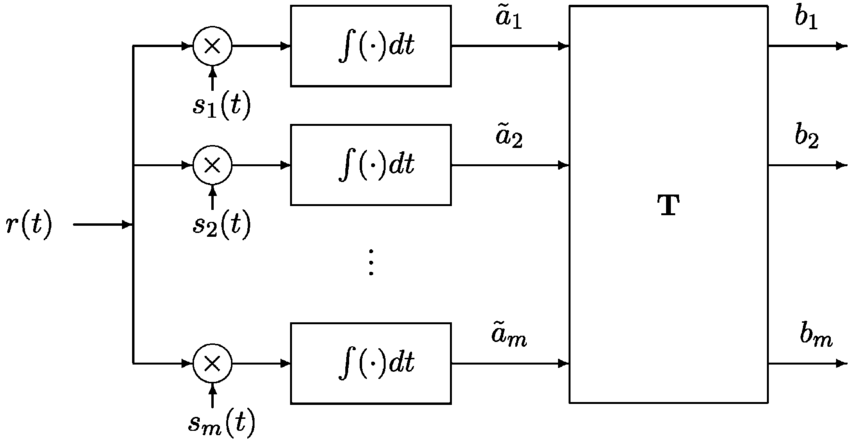

### Section 05

#### PSK Correlator Decoder and Detection

Since sinusoids with different phases have been used for encoding, there are two orthogonal functions and two correlators are needed for detection.


$$a_1 =\int_0^{T_b } r\left(t\right)\cos \left(2\pi r_b t\right)\textrm{dt}$$



$$a_2 =\int_0^{T_b } r\left(t\right)\sin \left(2\pi r_b t\right)\textrm{dt}$$


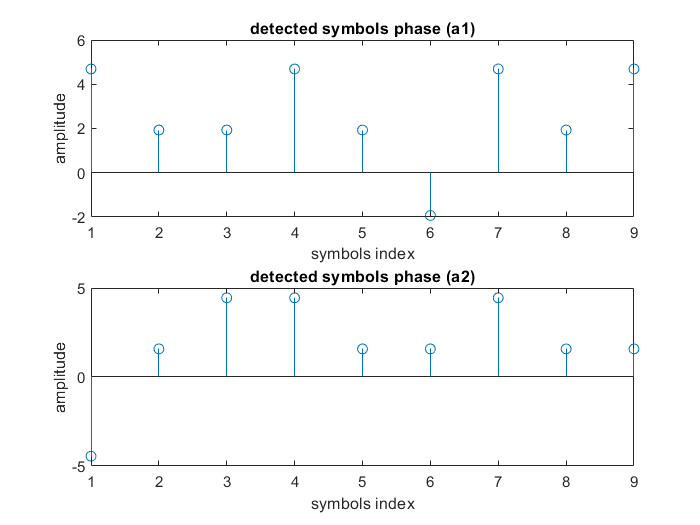

% decoding
rt = demodulated;
Ns = round(fc / rb);
a1 = zeros([1, floor(length(rt) * rb / fc)]);
a2 = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    % computing a1 (quadrature)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a1(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    % computing a2 (in-phase)
    % r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb + pi/2);
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a2(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    dcounter = dcounter + 1;
end
figure()
subplot(2, 1, 1); stem(a1); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a1)');
subplot(2, 1, 2); stem(a2); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a2)');

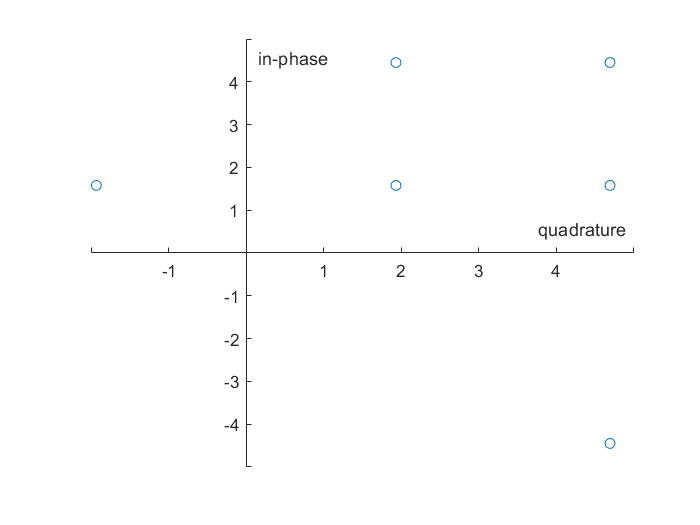

figure(); scatter(a1, a2);
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
xlabel('quadrature'); ylabel('in-phase');

% detection
%equalizer = [a1(1), a2(1)];
%centers_complex = a1 / equalizer(1) + 1j * a2 / equalizer(2)
equalizer = [1.9316,1.5790];
centers_complex =[1.00000000000000 + 1.00000000000000i,	-0.428571428571429 - 1.00000000000000i,	-1.00000000000000 - 0.999999999999999i,	-0.999999999999999 + 1.00000000000000i,	1.00000000000000 + 2.81818181818182i,	2.42857142857143 + 2.81818181818181i,	2.42857142857143 + 0.999999999999992i,	2.42857142857142 - 1.00000000000001i,	2.42857142857142 - 2.81818181818183i,	0.999999999999992 - 2.81818181818183i,	-0.285714285714301 - 3.72727272727273i,	-2.42857142857144 - 2.81818181818180i,	-2.42857142857143 - 0.999999999999984i,	-2.42857142857142 + 1.00000000000002i,	-2.42857142857141 + 2.81818181818184i,	-0.999999999999984 + 2.81818181818183i]

centers_complex =    1.0000 + 1.0000i  -0.4286 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 + 2.8182i   2.4286 + 2.8182i   2.4286 + 1.0000i   2.4286 - 1.0000i   2.4286 - 2.8182i   1.0000 - 2.8182i  -0.2857 - 3.7273i  -2.4286 - 2.8182i  -2.4286 - 1.0000i  -2.4286 + 1.0000i  -2.4286 + 2.8182i  -1.0000 + 2.8182i


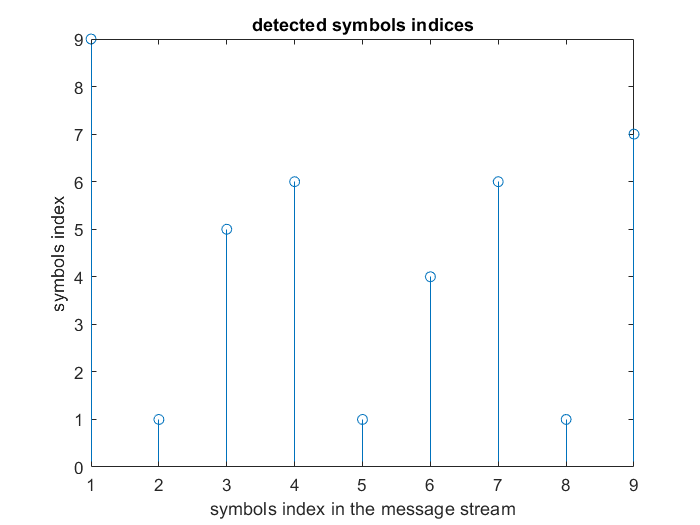


decoding_table = 1:M;
detected_indices = zeros([1, length(a1)]);
for n = 1:length(a1)
    distances = abs(centers_complex - (a1(n) / equalizer(1) + 1j * a2(n) / equalizer(2)));
    detected_indices(n) = decoding_table(distances == min(min(distances)));
end
figure()
stem(detected_indices); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 06

#### Noise

Noise is the impact of channel that signal transfer through.

The most common way to find the noise impact is Additive White Gaussian Noise (AWGN) model. In this model, the noise will be generted by a Gaussian distribution and added to the transmitted signal.

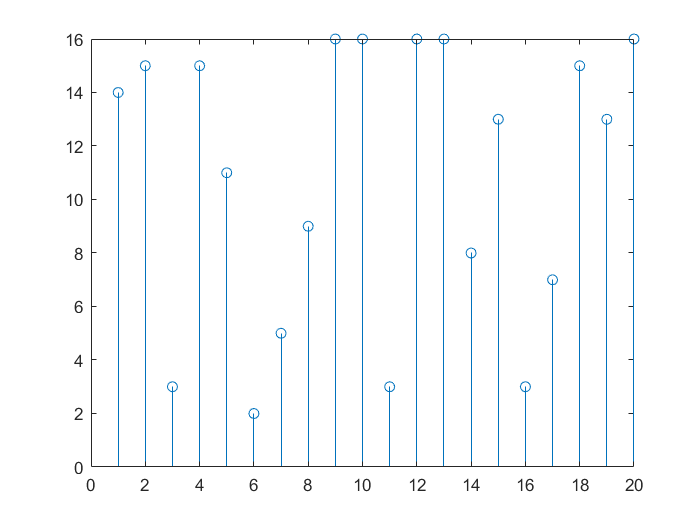

% generation of a random message with fixed length
rng(0);
Nm = 1000;
msg = randi(M, [1, Nm]);                            % message: a set of symbols
figure(); stem(msg(1:20));

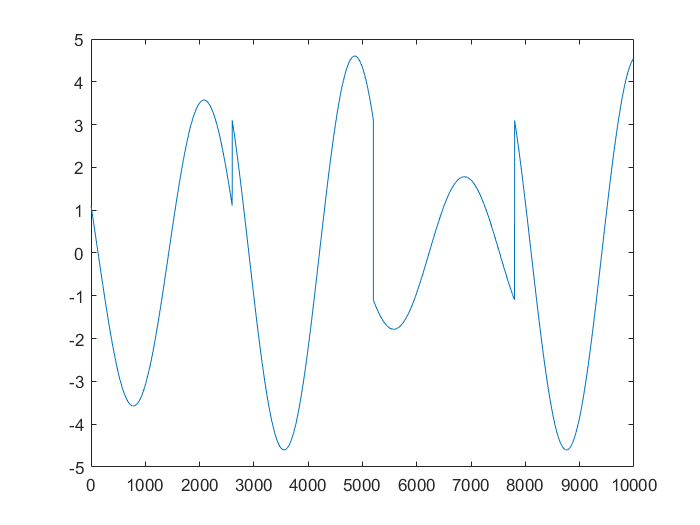

msg_coords = symbol_coords(symbol_set(msg));  % mepping the symbol to the amplitude
msg_coords_fs = rate_transition(msg_coords, rb, fs); % translate rate 1 to rate rb
t = (0:length(msg_coords_fs)-1)*Ts;                    % make the parameter time
signal = A * real(msg_coords_fs) .* cos(2 * pi * rb * t) + A * imag(msg_coords_fs) .* sin(2 * pi * rb * t);     % baseband signal
figure(); plot(signal(1:10000));

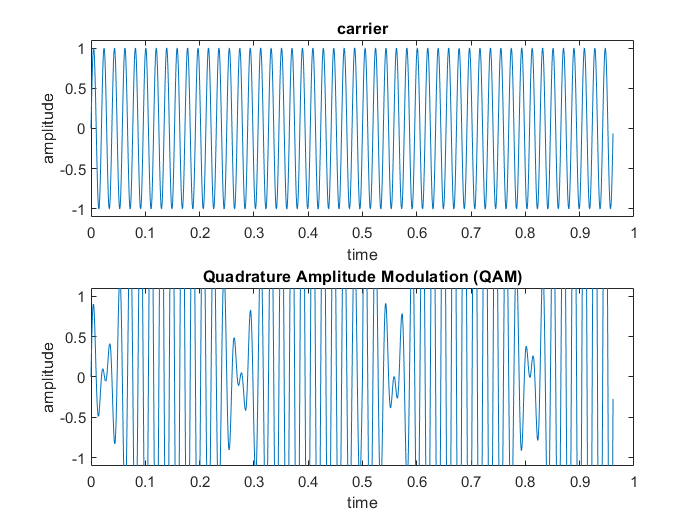

carrier = 1 * sin(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t(1:5000), carrier(1:5000)); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t(1:5000), modulated(1:5000)); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Quadrature Amplitude Modulation (QAM)');

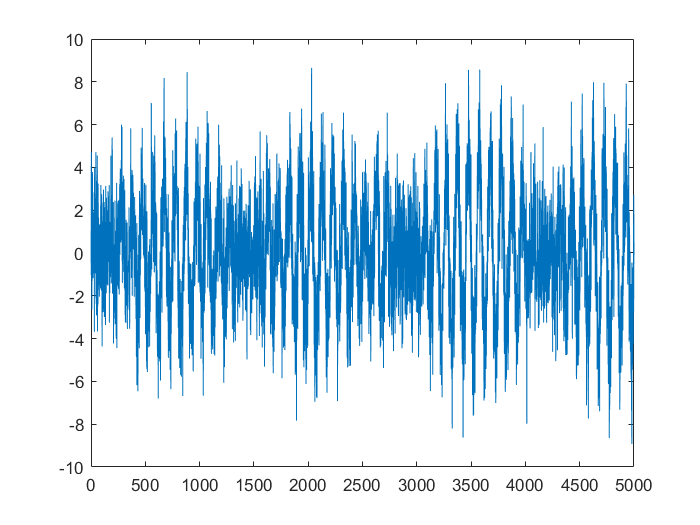

snr = 0;
noisy_signal = awgn(modulated, snr, 'measured');
figure(); plot(noisy_signal(1:5000));

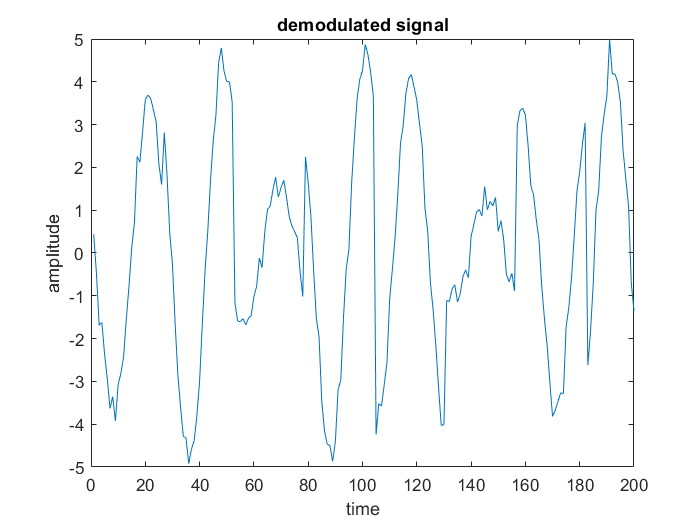

% demodulation
rt = noisy_signal;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
figure()
plot(demodulated(1:200)); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

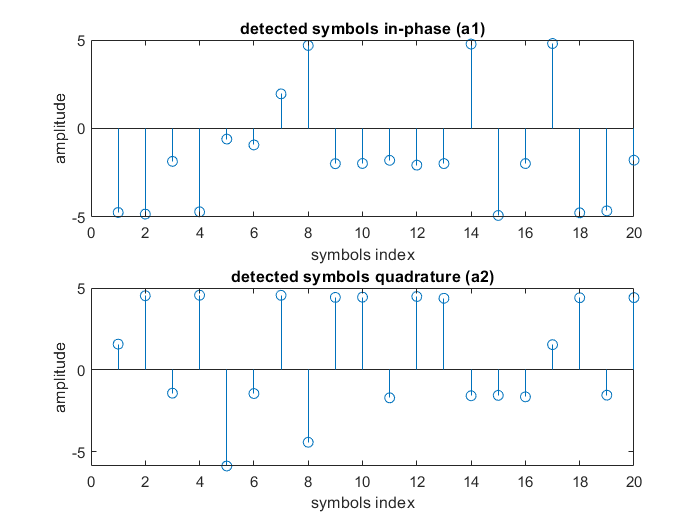

% decoding
rt = demodulated;
Ns = round(fc / rb);
a1 = zeros([1, floor(length(rt) * rb / fc)]);
a2 = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    % computing a1 (quadrature)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a1(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    % computing a2 (in-phase)
    % r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb + pi/2);
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a2(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    dcounter = dcounter + 1;
end
figure()
subplot(2, 1, 1); stem(a1(1:20)); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols in-phase (a1)');
subplot(2, 1, 2); stem(a2(1:20)); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols quadrature (a2)');

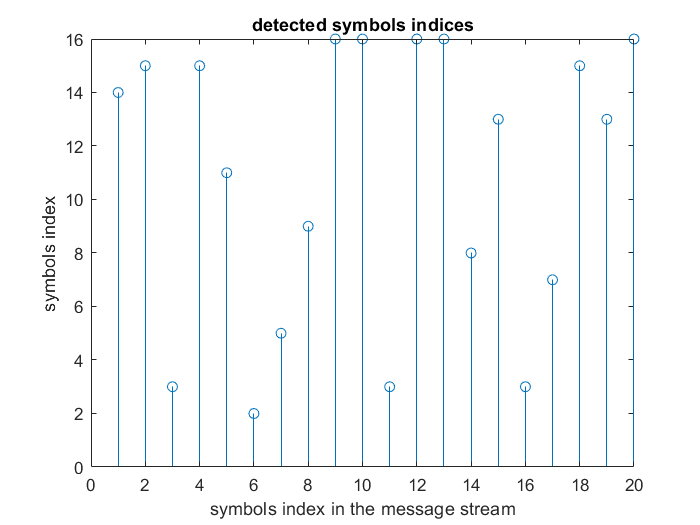

detected_indices = zeros([1, length(a1)]);
for n = 1:length(a1)
    distances = abs(centers_complex - (a1(n) / equalizer(1) + 1j * a2(n) / equalizer(2)));
    detected_indices(n) = decoding_table(distances == min(min(distances)));
end
figure()
stem(detected_indices(1:20)); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

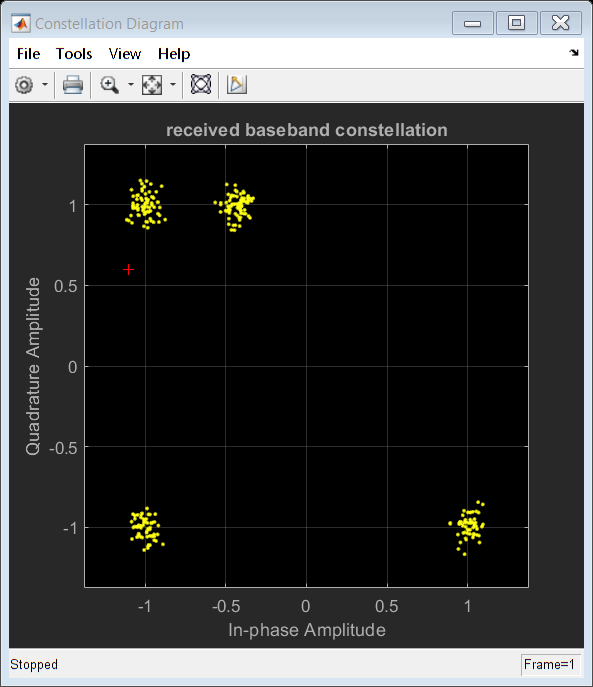

decoded_complex = a1 / equalizer(1) + 1j * a2 / equalizer(2);
constdiag = comm.ConstellationDiagram;
constdiag.Title = "received baseband constellation";
% constdiag.SymbolsToDisplay = 10000;
constdiag.ShowLegend = false;
constdiag.ReferenceConstellation = msg_coords';
constdiag(decoded_complex');
constdiag.release();    

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 07

Power spectrum of the **baseband** signal:

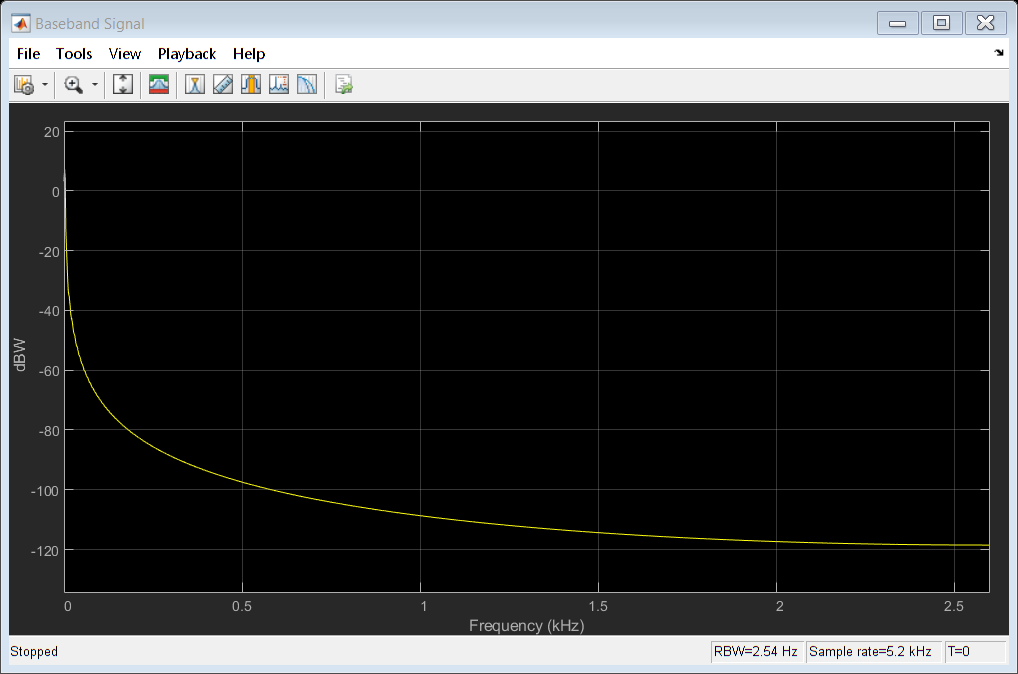

scope1 = dsp.SpectrumAnalyzer();
scope1.SampleRate = fs;
scope1.PlotAsTwoSidedSpectrum = false;
scope1.SpectrumUnits = "dBW";
scope1(signal');
scope1.Name = 'Baseband Signal';
release(scope1);

Power spectrum of the **carrier** signal:

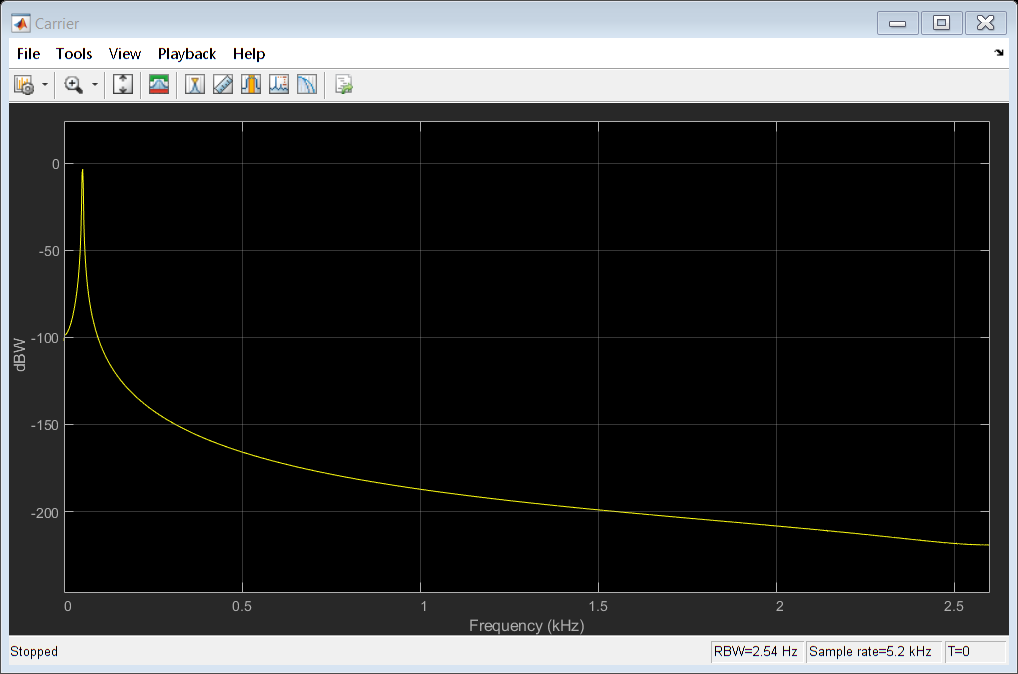

scope2 = dsp.SpectrumAnalyzer();
scope2.SampleRate = fs;
scope2.PlotAsTwoSidedSpectrum = false;
scope2.SpectrumUnits = "dBW";
scope2(carrier');
scope2.Name = 'Carrier';
release(scope2);

Power spectrum of the **modulated (passband)** signal:

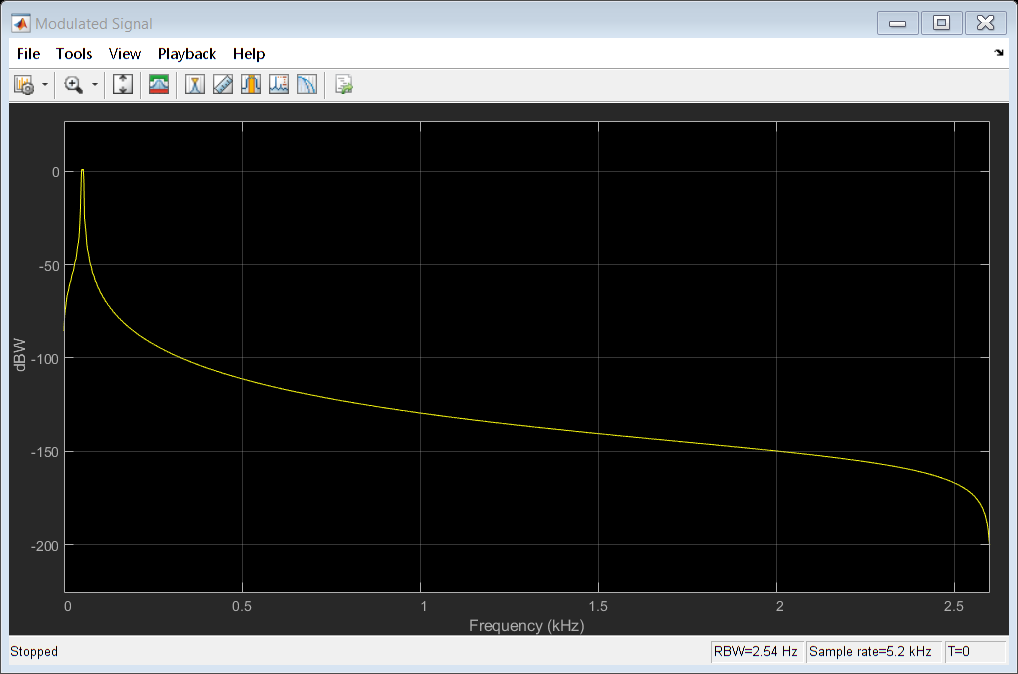

scope3 = dsp.SpectrumAnalyzer();
scope3.SampleRate = fs;
scope3.PlotAsTwoSidedSpectrum = false;
scope3.SpectrumUnits = "dBW";
scope3(modulated');
scope3.Name = 'Modulated Signal';
release(scope3);

Power spectrum of the **recieved** signal:

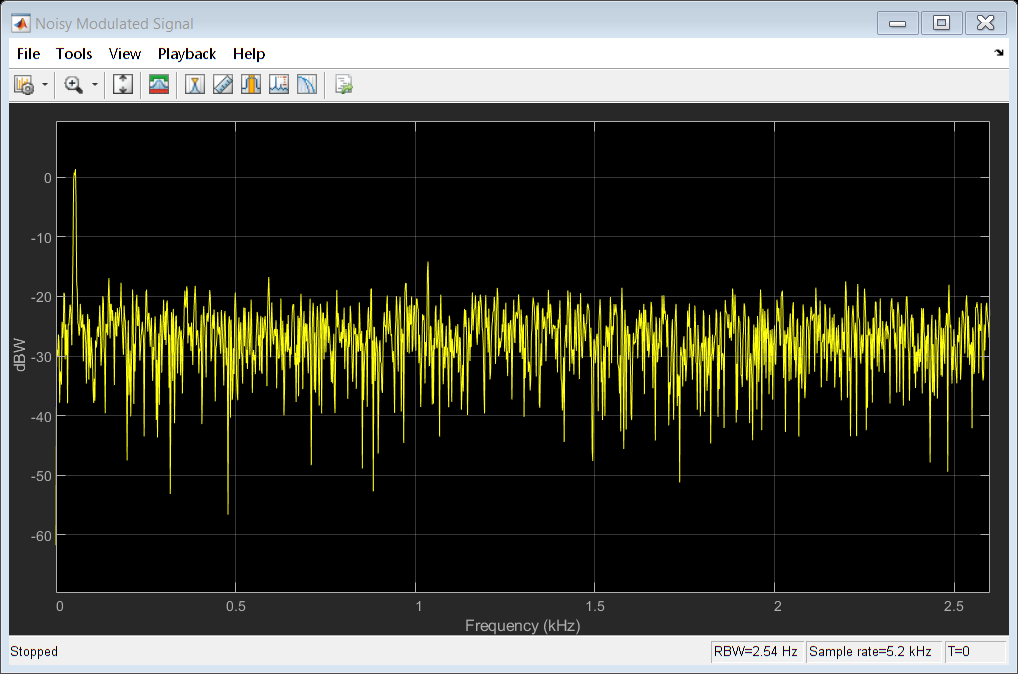

scope4 = dsp.SpectrumAnalyzer();
scope4.SampleRate = fs;
scope4.PlotAsTwoSidedSpectrum = false;
scope4.SpectrumUnits = "dBW";
scope4(noisy_signal');
scope4.Name = 'Noisy Modulated Signal';
release(scope4);

### Functions Definition

Rate transition:

function rt = rate_transition(s, f1, f2)
    if (f1 < f2)
        rt = repelem(s, floor(f2/f1));
        % x = 0:1/f1:((length(s)-1)*1/f1);
        % xq = 0:1/f2:((length(s)-1)*1/f1);
        % rt = interp1(x, s, xq, 'linear');
    else
        step = floor(f1/f2);
        rt = s(1:step:end);
    end
end